# Example 1: Horizontal line

This example presents the generation of  a turbulent wind field along with a horizontal line, assimilated to a bridge deck. The flow is assumed homogeneous and stationary along the deck.

## Run the function WindSim

The function windSim.m is called with a single input. This input is a text file named "INPUT.txt". In this example, this file is located in the same folder as windSim.

clearvars;close all;clc;
rng(1); % to ensure reproducibility of the example.
filename = 'INPUT_Example1.txt';
[u,v,w,t,nodes] = windSim(filename); 

Duration of target time series is 0.91 hours, i.e. 3.28e+03 sec 

Expected computation time: From 82 to 173 seconds 


## Time series overview

 Visualization of the spatial correlation of the time series

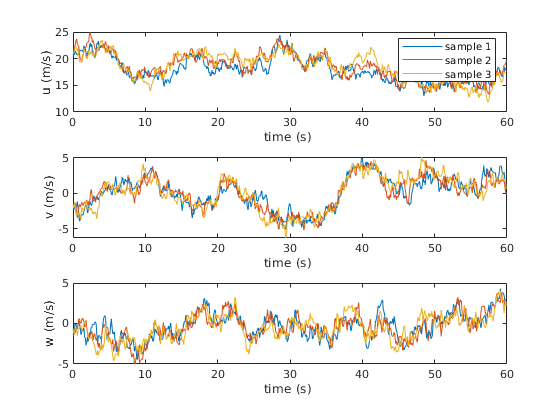

figure
subplot(311)
box on
axis tight
plot(t(1:600),u(1:3,1:600)+nodes.U(1:3)*ones(1,600))
xlabel('time (s) ');
ylabel('u (m/s)')
set(gcf,'color','w')
legend('sample 1','sample 2','sample 3');

subplot(312)
box on
axis tight
plot(t(1:600),v(1:3,1:600))
xlabel('time (s) ');
ylabel('v (m/s)')
set(gcf,'color','w')

subplot(313)
box on
axis tight
plot(t(1:600),w(1:3,1:600))
xlabel('time (s) ');
ylabel('w (m/s)')

set(gcf,'color','w')

## Standard deviation of wind velocity fluctuations

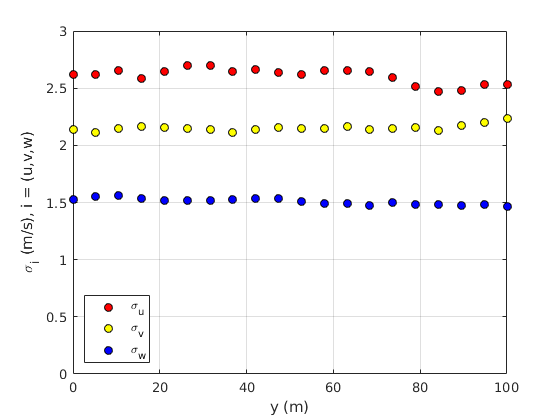

figure
box on;hold on,grid on
plot(nodes.Y, std(u,0,2),'ko','markerFaceColor','r')
plot(nodes.Y, std(v,0,2),'ko','markerFaceColor','y')
plot(nodes.Y, std(w,0,2),'ko','markerFaceColor','b')
ylim([0,3])
xlabel('y (m)')
ylabel('\sigma_{i} (m/s), i = (u,v,w)')
set(gcf,'color','w')
legend('\sigma_{u}','\sigma_{v}','\sigma_{w}','location','SouthWest')

## Turbulence Intensity

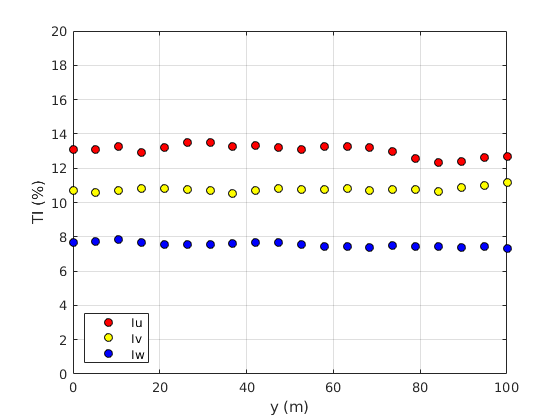

Iu = std(u,0,2)./nodes.U*100;
Iv = std(v,0,2)./nodes.U*100;
Iw = std(w,0,2)./nodes.U*100;

figure
box on;hold on,grid on
plot(nodes.Y,Iu,'ko','markerFaceColor','r')
plot(nodes.Y,Iv,'ko','markerFaceColor','y')
plot(nodes.Y,Iw,'ko','markerFaceColor','b')
ylim([0,20])
xlabel('y (m)')
ylabel('TI (%)')
set(gcf,'color','w')
legend('Iu','Iv','Iw','location','SouthWest')

## Comparison with Von Karman spectrum

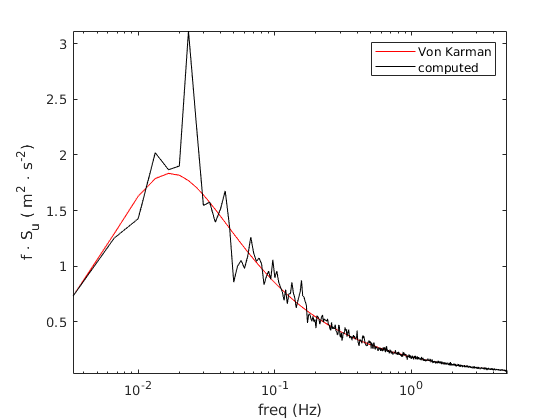

NBlock = 6; % number of blocks
dt = median(diff(t));
fs = 1/dt;
tmax = t(end);
[Nsensors,N]=size(u);
Ncoh = round(N/NBlock);% number of data point per block
clear Su Sv Sw

for ii=1:Nsensors,
    [Su(ii,:),f]=pwelch(u(ii,:),Ncoh,round(Ncoh/2),Ncoh,fs);
    [Sv(ii,:),f]=pwelch(v(ii,:),Ncoh,round(Ncoh/2),Ncoh,fs);
    [Sw(ii,:),f]=pwelch(w(ii,:),Ncoh,round(Ncoh/2),Ncoh,fs);
end


Su = mean(Su)'; % average the single-point spectra
Sv = mean(Sv)'; % average the single-point spectra
Sw = mean(Sw)'; % average the single-point spectra
coef=[-5/6, -11/6]; % empirical Von Karman spectra


Lu_target = 170;
Lv_target = 100;
Lw_target = 35;
stdU_target = 2.6;
stdV_target = 2.2;
stdW_target = 1.56;
U_target = 20;

n = Lu_target./U_target.*f';
Su_target =  U_target.^(-1).*4.*Lu_target.*stdU_target.^2.*(1+70.7.*n.^2).^(coef(1));

n = Lv_target./U_target.*f';
Sv_target=  U_target.^(-1).*4.*Lv_target.*stdV_target.^2.*(1+70.7.*4.*n.^2).^(coef(2)).*(1+188.4.*4*n.^2);

n = Lw_target./U_target.*f';
Sw_target=  U_target.^(-1).*4.*Lw_target.*stdW_target.^2.*(1+70.7.*4.*n.^2).^(coef(2)).*(1+188.4.*4*n.^2);



% plot the spectra
figure
box on;hold on
plot(f,f.*Su_target','r')
plot(f,f.*Su,'k')
legend('Von Karman','computed')
xlabel(' freq (Hz) ');
set(gca,'Xscale','log')
ylabel('f \cdot S_{u} ( m^2 \cdot s^{-2})')
set(gcf,'color','w')
axis tight

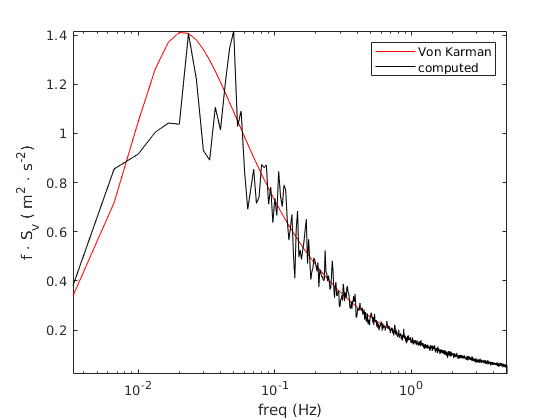


figure
box on;hold on
plot(f,f.*Sv_target','r')
plot(f,f.*Sv,'k')
legend('Von Karman','computed')
xlabel(' freq (Hz) ');
set(gca,'Xscale','log')
ylabel('f \cdot S_{v} ( m^2 \cdot s^{-2})')
set(gcf,'color','w')
axis tight

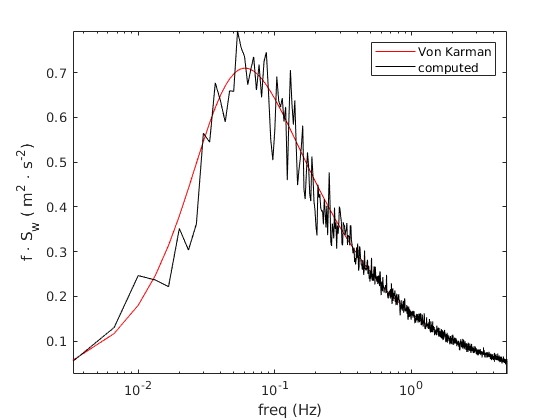


figure
box on;hold on
plot(f,f.*Sw_target','r')
plot(f,f.*Sw,'k')
legend('Von Karman','computed')
xlabel(' freq (Hz) ');
set(gca,'Xscale','log')
ylabel('f \cdot S_{w} ( m^2 \cdot s^{-2})')
set(gcf,'color','w')
axis tight

## Co-coherence calculation

The co-coherence is preferred to the magnitude squared coherence when it comes to wind flucutation

Nblock = 6;
Ncoh = round(N/NBlock);

if mod(Ncoh,2),
    cocoh = zeros(Nsensors,Nsensors,round(Ncoh/2));
else
    cocoh = zeros(Nsensors,Nsensors,round(Ncoh/2)+1);
end
% computation of the cocoherence using the function coherence
for ii=1:Nsensors,
    for jj=1:Nsensors,
        [cocoh(ii,jj,:),~,freq] = coherence(u(ii,:),u(jj,:),Ncoh,round(Ncoh/2),Ncoh,fs);
    end
end

% matrix distance along y
dy = zeros(Nsensors,Nsensors); 
for kk= 1:Nsensors,
    for mm = 1:Nsensors,
        dy(kk,mm) = abs(nodes.Y(kk)-nodes.Y(mm));
    end
end

% average of coherence over same cross-flow separations
cocoh = reshape(cocoh,Nsensors*Nsensors,[]);
[uniqueDist]=unique(round(dy(:)*100)/100); % average at +/- 1 cm
meanCoCoh = zeros(numel(uniqueDist),size(cocoh,2));
for ii=1:numel(uniqueDist),
    ind = find(round(dy(:)*100)/100==uniqueDist(ii));
    meanCoCoh(ii,:)=nanmean(cocoh(ind,:));
end

## Co-coherence verification

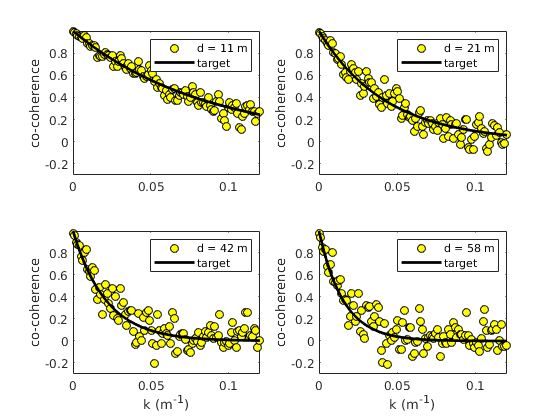

% choice of 4 target distances
distTarget = [10,20,40,60];
% wave number k
k = 2*pi*freq./nodes.U(1);
figure
for ii=1:4,
    [~,indDist] = min(abs(uniqueDist-distTarget(ii)));
    subplot(2,2,ii)
    box on;hold on
    plot(k,meanCoCoh(indDist,:),'ko','markerfacecolor','y');
    plot(k,exp(-7.*dy(1,indDist).*freq/nodes.U(1)),'k','linewidth',2);
    legend(['d = ',num2str(uniqueDist(indDist),2),' m'],'target');
    xlim([0,0.12])
    ylim([-0.3,1])
    ylabel('co-coherence')
    if ii>2,
        xlabel('k (m^{-1})')
    end
    set(gcf,'color','w')
end

## Conclusion

A simple example of turbulent wind simulation is presented here. Because the simulation procedure belongs to Monte-Carlo schemes, the measured parameters are not always expected to perfectly fit with the target ones. At every new simulation, different time series are obtained. The user is free to implement new wind spectra or new coherence models.